# **Plots**

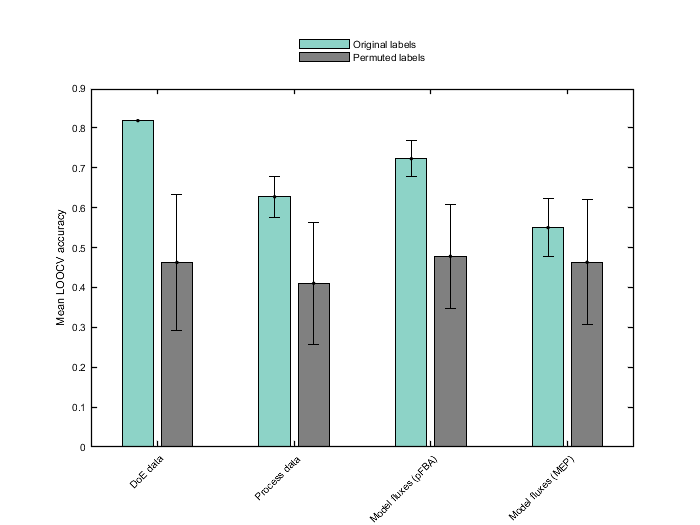

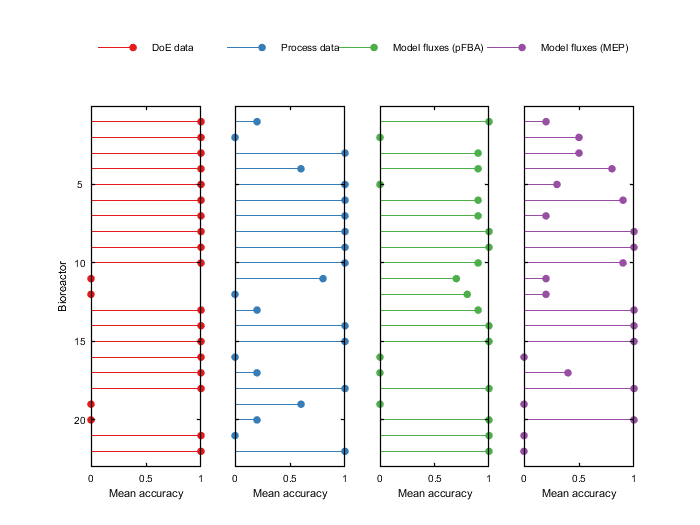

clear
addpath('..\..\packages\cbrewer');
addpath('..\..\packages\alluvialflow');
if not(isfolder('..\plots'))
    mkdir('..\plots')
end
addpath(genpath('..\data\'))
addpath('..\plots')

# Figure 2

## PCA post-induction with end data

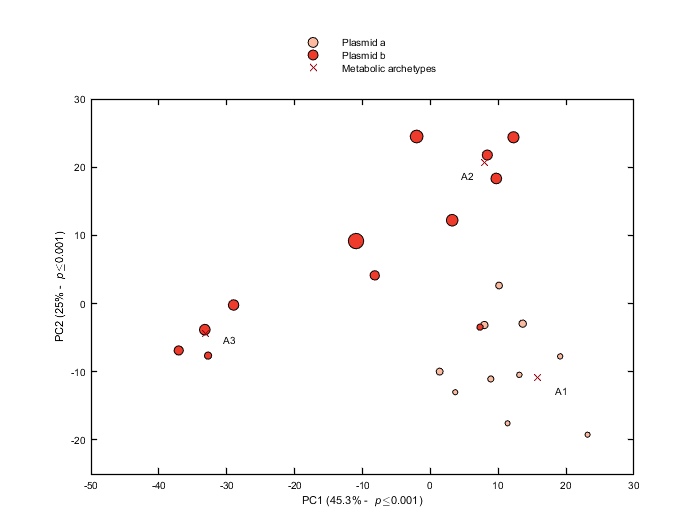

load end_pFBA_fluxes.mat
load AA_results_archetypes.mat
load PCA_permutation_test.mat
load titres.mat
load DoE_and_offline_data.mat

titres.data_matrix = titres.data_matrix([2:5, 7:24], :);
titres.labels = titres.labels([2:5, 7:24]);

[coeff,score,latent,tsquared,explained,mu] = pca(zscore(fluxes));
plasmid_idx = strcmp(DoE_and_offline_data.Plasmid, 'a');

% colors
cb1 = cbrewer('seq', 'Reds', 8);

figure
hold on 
h1 = scatter(score(plasmid_idx,1), score(plasmid_idx,2), (10+10*titres.data_matrix(plasmid_idx,1)), ...
    cb1(3,:), 'o', 'filled', 'MarkerEdgeColor', 'k');
h2 = scatter(score(~plasmid_idx,1), score(~plasmid_idx,2), (10+10*titres.data_matrix(~plasmid_idx,1)), ...
    cb1(6,:), 'o', 'filled', 'MarkerEdgeColor', 'k');
h3 = scatter(XC'*coeff(:,1), XC'*coeff(:,2), 22, cb1(8,:), 'x');
h4 = text(XC'*coeff(:,1)+[4.5;-1.5;4.5], XC'*coeff(:,2)-[3;3;2], {'A1', 'A2', 'A3'}, ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 6);
hold off
set(gca, 'LineWidth', 0.7, 'FontName', 'Arial', 'FontSize', 6, 'XColor', 'k', 'YColor', 'k')
set(gca, 'xlim', [-50, 30], 'ylim', [-25, 30], 'ytick', -20:10:30)
xlabel(['PC1 (', num2str(round(explained(1), 1)), '% - \it p\rm\leq' num2str(p_lambdas(1)) ')'], 'FontSize', 8, 'FontName', 'Arial')
ylabel(['PC2 (', num2str(round(explained(2), 1)), '% - \it p\rm\leq' num2str(p_lambdas(2)) ')'], 'FontSize', 8, 'FontName', 'Arial')
l = legend({'Plasmid a', 'Plasmid b', 'Metabolic archetypes'}, 'Location', 'northoutside', 'FontSize', 6);
set(l, 'Box', 'off');
box on

my_print('..\plots\PCA', 3, 3*8/5.5, 'landscape')

## **Archetype pathway enrichment**

load AA_results_archetype_enrichment.mat

pathways = unique([enrichment_table{1}(2:end, 3); enrichment_table{2}(2:end, 3); enrichment_table{3}(2:end, 3)]);
pvalues = nan(length(pathways), 3);
[a, b] = ismember(pathways, enrichment_table{1}(:, 3));
pvalues(a, 1) = cell2mat(enrichment_table{1}(b(a), 2));
[a, b] = ismember(pathways, enrichment_table{2}(:, 3));
pvalues(a, 2) = cell2mat(enrichment_table{2}(b(a), 2));
[a, b] = ismember(pathways, enrichment_table{3}(:, 3));
pvalues(a, 3) = cell2mat(enrichment_table{3}(b(a), 2));
pvalues = round(pvalues, 2, 'significant');

h = heatmap({'A1','A2','A3'}, pathways, pvalues, ...
    'MissingDataLabel', 'No data', ...
    'CellLabelFormat', '%.1e', ...
    'FontSize', 6, 'FontName', 'Arial');

% color map
cmap = h.Colormap;
n = 50;               %// number of colors
R = [linspace(cmap(end, 1), 1, n) ones(1, 50-n)];  %// Red from 1 to 0
G = [linspace(cmap(end, 2), 1, n) ones(1, 50-n)];   %// Green all zero
B = [linspace(cmap(end, 3), 1, n) ones(1, 50-n)];  %// Blue from 0 to 1
h.Colormap = [R' G' B']

h =   HeatmapChart with properties:

        XData: {3×1 cell}
        YData: {35×1 cell}
    ColorData: [35×3 double]

  Show all properties


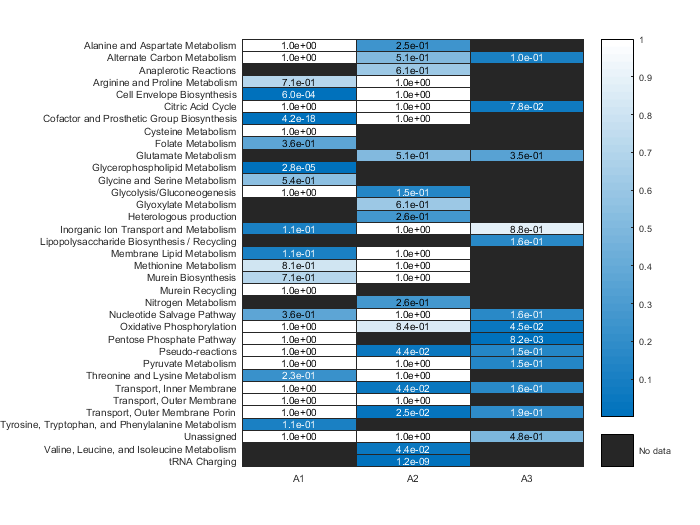


my_print('..\plots\AA enrichment', 4.8, 5, 'landscape')

## **SVM pathway enrichment**

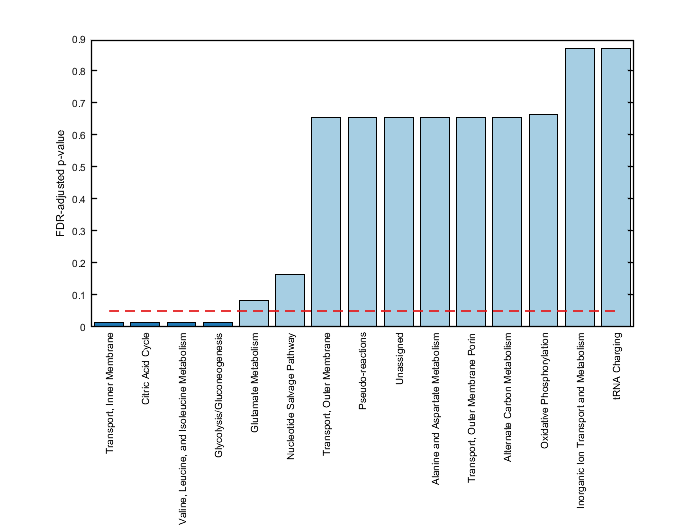

load SVM_results_pFBA_end_weight_enrichment.mat

pvalues = cell2mat(enrichment_table(2:end, 2));
pvalues(pvalues < 1e-6) = 1e-6;
num_sig_pvalues = sum(pvalues <= 0.05);
labels = enrichment_table(2:end, 3);
% labels = replace(labels, 'Metabolism', 'met.');
% labels = replace(labels, 'metabolism', 'met.');
labels = reordercats(categorical(labels), labels);
cb1 = cbrewer('qual', 'Paired', 3);
cb2 = cbrewer('qual', 'Set1', 3);

figure
h = bar(labels, pvalues);
set(gca, 'yminortick', 'off', 'xticklabelrotation', 90)
set(gca, 'LineWidth', 0.7, 'FontName', 'Arial', 'FontSize', 6, 'XColor', 'k', 'YColor', 'k')
g = gca;
g.XAxis.TickLength = [0 0];
h.FaceColor = 'flat';
h.CData(1:num_sig_pvalues, :) = repmat(cb1(2, :), num_sig_pvalues, 1);
h.CData(num_sig_pvalues+1:end, :) = repmat(cb1(1, :), length(labels)-num_sig_pvalues, 1);
ylabel('FDR-adjusted p-value', 'FontSize', 8, 'FontName', 'Arial')

hold on
l = line(labels, 0.05*ones(length(labels), 1), 'LineStyle', '--', 'LineWidth', 1, 'Color', cb2(1, :));
hold off

my_print('..\plots\SVM enrichment', 3.5, 3.5, 'landscape')

# Figure 3

## **PLSCA variable relationship**

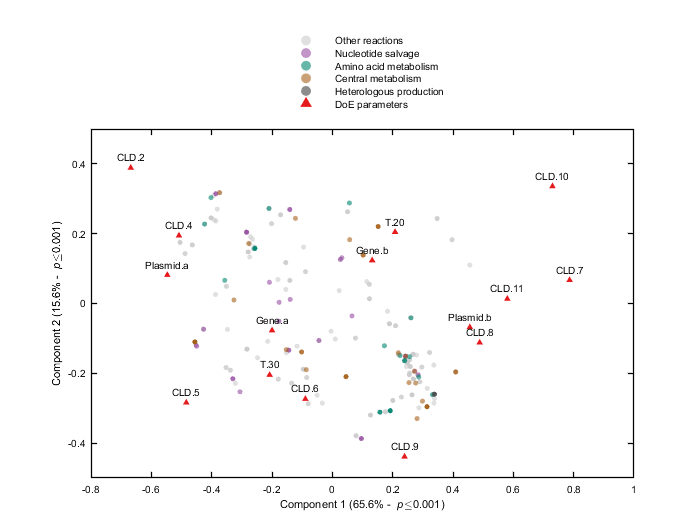

load end_pFBA_fluxes.mat
all_rxns = rxns;
load PLSCA_results.mat

% take only factor scores for the positive components of the Escofier transform
fluxes_factor_scores = fluxes_factor_scores(length(fluxes_factor_scores)/2+1:end, :);
fluxes_BSRs = fluxes_BSRs(length(fluxes_BSRs)/2+1:end, :);

% select variables with a significant score for either component 1 or 2
fluxes_factor_scores = fluxes_factor_scores(ismember(rxns, bootstrap_rxns), :);
fluxes_factor_scores = fluxes_factor_scores(or(abs(fluxes_BSRs(:, 1)) > 2, abs(fluxes_BSRs(:, 2)) > 2), :);
bootstrap_rxns = bootstrap_rxns(or(abs(fluxes_BSRs(:, 1)) > 2, abs(fluxes_BSRs(:, 2)) > 2));
DoE_factor_scores = DoE_factor_scores(ismember(DoE_variables', bootstrap_DoE_variables), :);
DoE_factor_scores = DoE_factor_scores(or(abs(DoE_BSRs(:, 1)) > 2, abs(DoE_BSRs(:, 2)) > 2), :);
bootstrap_DoE_variables = bootstrap_DoE_variables(or(abs(DoE_BSRs(:, 1)) > 2, abs(DoE_BSRs(:, 2)) > 2));

% get subSystems for bootstrap reactions
bootstrap_rxns = regexprep(bootstrap_rxns, '^v_', '');
[a, b] = ismember(bootstrap_rxns, all_rxns);
bootstrap_subSystems = subSystems(b(a));
central_rxns_idx = strcmp(bootstrap_subSystems, 'Citric Acid Cycle') | ...
    strcmp(bootstrap_subSystems, 'Glycolysis/Gluconeogenesis') | ...
    strcmp(bootstrap_subSystems, 'Oxidative Phosphorylation') | ...
    strcmp(bootstrap_subSystems, 'Pentose Phosphate Pathway');% | ...
    %strcmp(bootstrap_subSystems, 'Pyruvate Metabolism');
aa_rxns_idx = strcmp(bootstrap_subSystems, 'Alanine and Aspartate Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Arginine and Proline Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Cysteine Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Glutamate Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Glycine and Serine Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Histidine Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Methionine Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Threonine and Lysine Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Tyrosine, Tryptophan, and Phenylalanine Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Valine, Leucine, and Isoleucine Metabolism');
nucleotide_rxns_idx = strcmp(bootstrap_subSystems, 'Nucleotide Salvage Pathway');
production_rxns_idx = strcmp(bootstrap_subSystems, 'Heterologous production');
other_rxns_idx = ~any([central_rxns_idx, aa_rxns_idx, nucleotide_rxns_idx, production_rxns_idx], 2);

% colors
cb1 = cbrewer('div', 'BrBG', 5);
cb2 = cbrewer('qual', 'Set1', 5);
cb3 = cbrewer('div', 'RdGy', 5);

figure
hold on
scatter(fluxes_factor_scores(other_rxns_idx, 1), fluxes_factor_scores(other_rxns_idx, 2), 10, [0.8, 0.8, 0.8], ...
    'filled', 'MarkerFaceAlpha', 0.6);
scatter(fluxes_factor_scores(nucleotide_rxns_idx, 1), fluxes_factor_scores(nucleotide_rxns_idx, 2), 10, cb2(4, :), ...
    'filled', 'MarkerFaceAlpha', 0.6);
scatter(fluxes_factor_scores(aa_rxns_idx, 1), fluxes_factor_scores(aa_rxns_idx, 2), 10, cb1(5, :), ...
    'filled', 'MarkerFaceAlpha', 0.6);
scatter(fluxes_factor_scores(central_rxns_idx, 1), fluxes_factor_scores(central_rxns_idx, 2), 10, cb1(1, :), ...
    'filled', 'MarkerFaceAlpha', 0.6);
scatter(fluxes_factor_scores(production_rxns_idx, 1), fluxes_factor_scores(production_rxns_idx, 2), 10, cb3(5, :), ...
    'filled', 'MarkerFaceAlpha', 0.6);
scatter(DoE_factor_scores(:, 1), DoE_factor_scores(:, 2), 12, cb2(1, :), 'filled', '^', 'MarkerFaceAlpha', 1);
text(DoE_factor_scores(:, 1), DoE_factor_scores(:, 2)+0.01, bootstrap_DoE_variables, ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center', 'FontSize', 6)
hold off

set(gca, 'LineWidth', 0.7, 'FontName', 'Arial', 'FontSize', 6, 'XColor', 'k', 'YColor', 'k', 'xlim', [-0.8, 1], ...
    'ylim', [-0.5, 0.5], 'ytick', -0.4:0.2:0.4)
xlabel(['Component 1 (', num2str(round(explained(1), 1)), '% - \it p\rm\leq' num2str(p_lambdas(1)) ')'], 'FontSize', 8)
ylabel(['Component 2 (', num2str(round(explained(2), 1)), '% - \it p\rm\leq' num2str(p_lambdas(2)) ')'], 'FontSize', 8)
l = legend({'Other reactions'; 'Nucleotide salvage'; 'Amino acid metabolism'; 'Central metabolism'; ...
    'Heterologous production'; 'DoE parameters'}, 'Location', 'northoutside', 'FontSize', 6);
set(l, 'Box', 'off');
box on

my_print('..\plots\PLSCA factor scores', 4, 4*18/10, 'landscape')

## **PLSCA focus on plasmid a and T 20**

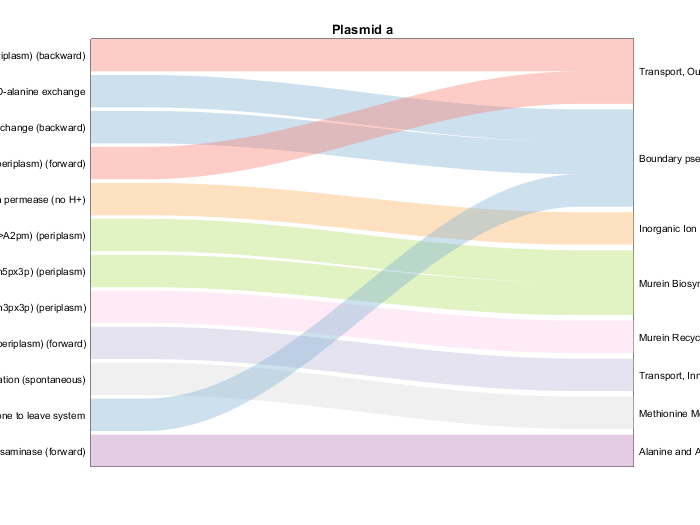

load end_pFBA_fluxes.mat
all_rxns = rxns;
load PLSCA_results.mat
load iEC1356_Bl21DE3.mat

% take only factor scores for the positive components of the Escofier transform
fluxes_factor_scores = fluxes_factor_scores(length(fluxes_factor_scores)/2+1:end, :);
fluxes_BSRs = fluxes_BSRs(length(fluxes_BSRs)/2+1:end, :);

% select variables with a significant score for either component 1 or 2
fluxes_factor_scores = fluxes_factor_scores(ismember(rxns, bootstrap_rxns), :);
fluxes_factor_scores = fluxes_factor_scores(or(abs(fluxes_BSRs(:, 1)) > 2, abs(fluxes_BSRs(:, 2)) > 2), :);
bootstrap_rxns = bootstrap_rxns(or(abs(fluxes_BSRs(:, 1)) > 2, abs(fluxes_BSRs(:, 2)) > 2));
DoE_factor_scores = DoE_factor_scores(ismember(DoE_variables', bootstrap_DoE_variables), :);
DoE_factor_scores = DoE_factor_scores(or(abs(DoE_BSRs(:, 1)) > 2, abs(DoE_BSRs(:, 2)) > 2), :);
bootstrap_DoE_variables = bootstrap_DoE_variables(or(abs(DoE_BSRs(:, 1)) > 2, abs(DoE_BSRs(:, 2)) > 2));

% fix subsystem and reaction names
subSystems = strrep(subSystems, 'Pseudo-reactions', 'Boundary pseudo-reactions');
all_rxns = regexprep(all_rxns, '^v_', '');
bootstrap_rxns = regexprep(bootstrap_rxns, '^v_', '');

% calculate Euclidean distance between flux and DoE variables
D = pdist2(fluxes_factor_scores(:, 1:2), DoE_factor_scores(:, 1:2));


% rank reactions based on distance from Plasmid.a
[sorted_D_plasmida, sort_idx] = sort(D(:, strcmp(bootstrap_DoE_variables, 'Plasmid.a')));
plasmida_rank_rxns = bootstrap_rxns(sort_idx);
[~, b] = ismember(plasmida_rank_rxns, all_rxns);
plasmida_rank_subSystems = subSystems(b);

% fetch rxn names of top-ranked rxns
plasmida_rank_rxns_cut = regexprep(plasmida_rank_rxns, '_f$', '');
plasmida_rank_rxns_cut = regexprep(plasmida_rank_rxns_cut, '_b$', '');
num_top_ranks = 12;
iEC1356_Bl21DE3.rxns = strrep(iEC1356_Bl21DE3.rxns, 'ASPt2pp_copy2', 'ASPt2pp');
[~, b] = ismember(plasmida_rank_rxns_cut(1:num_top_ranks), iEC1356_Bl21DE3.rxns);
plasmida_rank_rxnNames = iEC1356_Bl21DE3.rxnNames(b);

% add directionality information to rxn names
idx = endsWith(plasmida_rank_rxns(1:num_top_ranks), '_f');
suffix = cell(num_top_ranks, 1);
suffix(idx) = repmat({' (forward)'}, sum(idx), 1);
plasmida_rank_rxnNames = strcat(plasmida_rank_rxnNames, suffix);
idx = endsWith(plasmida_rank_rxns(1:num_top_ranks), '_b');
suffix = cell(num_top_ranks, 1);
suffix(idx) = repmat({' (backward)'}, sum(idx), 1);
plasmida_rank_rxnNames = strcat(plasmida_rank_rxnNames, suffix);


% rank reactions based on distance from T.20
[sorted_D_T20, sort_idx] = sort(D(:, strcmp(bootstrap_DoE_variables, 'T.20')));
T20_rank_rxns = bootstrap_rxns(sort_idx);
[~, b] = ismember(T20_rank_rxns, all_rxns);
T20_rank_subSystems = subSystems(b);

% fetch rxn names of top-ranked rxns
T20_rank_rxns_cut = regexprep(T20_rank_rxns, '_f$', '');
T20_rank_rxns_cut = regexprep(T20_rank_rxns_cut, '_b$', '');
num_top_ranks = 12;
[~, b] = ismember(T20_rank_rxns_cut(1:num_top_ranks), iEC1356_Bl21DE3.rxns);
T20_rank_rxnNames = iEC1356_Bl21DE3.rxnNames(b);

% add directionality information to rxn names
idx = endsWith(T20_rank_rxns(1:num_top_ranks), '_f');
suffix = cell(num_top_ranks, 1);
suffix(idx) = repmat({' (forward)'}, sum(idx), 1);
T20_rank_rxnNames = strcat(T20_rank_rxnNames, suffix);
idx = endsWith(T20_rank_rxns(1:num_top_ranks), '_b');
suffix = cell(num_top_ranks, 1);
suffix(idx) = repmat({' (backward)'}, sum(idx), 1);
T20_rank_rxnNames = strcat(T20_rank_rxnNames, suffix);


% set up plot variables
all_right_labels = unique([T20_rank_subSystems(1:num_top_ranks); plasmida_rank_subSystems(1:num_top_ranks)], 'stable');
cb1 = cbrewer('qual', 'Set3', 10);

% plot rank for Plasmid.a
left_labels = plasmida_rank_rxnNames;
right_labels = unique(plasmida_rank_subSystems(1:num_top_ranks), 'stable');
sankey_data = zeros(num_top_ranks, length(right_labels));
for i = 1:length(right_labels)
    sankey_data(strcmp(plasmida_rank_subSystems(1:num_top_ranks), right_labels(i)), i) = 1;
end
[~, b] = ismember(right_labels, all_right_labels);
colors = cb1(b, :);
h = alluvialflow(sankey_data, left_labels, right_labels, 'Plasmid a', colors);

my_print('..\plots\Plasmid-a-associated reactions', 2, 3, 'landscape')

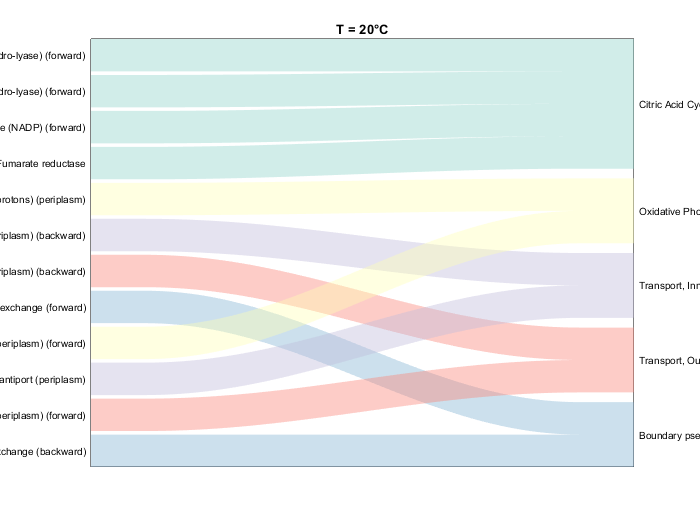


% plot rank for Gene.b
left_labels = T20_rank_rxnNames;
right_labels = unique(T20_rank_subSystems(1:num_top_ranks), 'stable');
sankey_data = zeros(num_top_ranks, length(right_labels));
for i = 1:length(right_labels)
    sankey_data(strcmp(T20_rank_subSystems(1:num_top_ranks), right_labels(i)), i) = 1;
end
[~, b] = ismember(right_labels, all_right_labels);
colors = cb1(b, :);
h = alluvialflow(sankey_data, left_labels, right_labels, 'T = 20°C', colors);

my_print('..\plots\T-20-associated reactions', 2, 3, 'landscape')

# Figure 5

## SVM total accuracy

load SVM_results_DoE_pre.mat
SVM_results_DoE = SVM_results;
load SVM_results_DoE_pre_label_permutation.mat
SVM_results_DoE_perm = SVM_results;
load SVM_results_concentrations_post.mat
SVM_results_concentrations = SVM_results;
load SVM_results_concentrations_post_label_permutation.mat
SVM_results_concentrations_perm = SVM_results;
load SVM_results_pFBA_post.mat
SVM_results_pFBA = SVM_results;
load SVM_results_pFBA_post_label_permutation.mat
SVM_results_pFBA_perm = SVM_results;
load SVM_results_MEP_post.mat
SVM_results_MEP = SVM_results;
load SVM_results_MEP_post_label_permutation.mat
SVM_results_MEP_perm = SVM_results;
clear SVM_results

% calculate mean and std of accuracy
labels = {'DoE data', 'Process data', 'Model fluxes (pFBA)', 'Model fluxes (MEP)'};
accuracies = nan(10, length(labels));
for i = 1:10
    accuracies(i, 1) = acc(SVM_results_DoE.predicted(:, 1, i), SVM_results_DoE.true(:, 1, i));
    accuracies(i, 2) = acc(SVM_results_concentrations.predicted(:, 1, i), SVM_results_concentrations.true(:, 1, i));
    accuracies(i, 3) = acc(SVM_results_pFBA.predicted(:, 1, i), SVM_results_pFBA.true(:, 1, i));
    accuracies(i, 4) = acc(SVM_results_MEP.predicted(:, 1, i), SVM_results_MEP.true(:, 1, i));
end
accuracies_perm = nan(100, length(labels));
for i = 1:100
    accuracies_perm(i, 1) = acc(SVM_results_DoE_perm.predicted(:, 1, i), SVM_results_DoE_perm.true(:, 1, i));
    accuracies_perm(i, 2) = acc(SVM_results_concentrations_perm.predicted(:, 1, i), SVM_results_concentrations_perm.true(:, 1, i));
    accuracies_perm(i, 3) = acc(SVM_results_pFBA_perm.predicted(:, 1, i), SVM_results_pFBA_perm.true(:, 1, i));
    accuracies_perm(i, 4) = acc(SVM_results_MEP_perm.predicted(:, 1, i), SVM_results_MEP_perm.true(:, 1, i));
end
mean_acc = [mean(accuracies)' mean(accuracies_perm)'];
std_acc = [std(accuracies)' std(accuracies_perm)'];


% colors
cb1 = cbrewer('qual', 'Set3', 3);
% plot
figure
hBar = bar(mean_acc, 'FaceColor', 'flat');
hBar(1).CData = cb1(1, :);
hBar(2).CData = [0.5 0.5 0.5];

hold on
ctr = zeros(size(mean_acc, 2), size(mean_acc, 1));
ydt = zeros(size(mean_acc, 2), size(mean_acc, 1));
for k = 1:size(mean_acc, 2)
    ctr(k,:) = bsxfun(@plus, hBar(k).XData, hBar(k).XOffset'); % Note: ‘XOffset’ Is An Undocumented Feature, This Selects The ‘bar’ Centres
    ydt(k,:) = hBar(k).YData;
end
errorbar(ctr, ydt, std_acc.', '.k')
set(gca, 'LineWidth', 0.7, 'FontName', 'Arial', 'FontSize', 6, 'XColor', 'k', 'YColor', 'k', 'xticklabel', labels)
rotateXLabels(gca, 45)
ylabel('Mean LOOCV accuracy', 'FontSize', 8)

l = legend({'Original labels', 'Permuted labels'}, 'Location', 'northoutside', 'FontSize', 6);
set(l, 'Box', 'off');
    
my_print('..\plots\SVM total accuracy', 3, 3, 'landscape')

## SVM bioreactor accuracy

load SVM_results_DoE_pre.mat
SVM_results_DoE = SVM_results;
load SVM_results_concentrations_post.mat
SVM_results_concentrations = SVM_results;
load SVM_results_pFBA_post.mat
SVM_results_pFBA = SVM_results;
load SVM_results_MEP_post.mat
SVM_results_MEP = SVM_results;
clear SVM_results

% colors
cb1 = cbrewer('qual', 'Set1', 4);
% plot
figure
subplot(1,4,1)
p1 = stem(SVM_results_DoE.bioreactor_accuracy, 'filled', 'Color', cb1(1, :), 'MarkerSize', 4);
view(90, 90)
xlim([0, 23])
set(gca, 'xticklabel', [5 10 15 20], 'xtick', [5 10 15 20])
set(gca, 'LineWidth', 0.7, 'FontName', 'Arial', 'FontSize', 6, 'XColor', 'k', 'YColor', 'k')
xlabel('Bioreactor', 'FontSize', 8)
ylabel('Mean accuracy', 'FontSize', 8)
l1 = legend({'DoE data'}, 'Location', 'northoutside', 'FontSize', 6);
set(l1, 'Box', 'off');
subplot(1,4,2)
p2 = stem(SVM_results_concentrations.bioreactor_accuracy, 'filled', 'Color', cb1(2, :), 'MarkerSize', 4);
view(90, 90)
xlim([0, 23])
set(gca, 'xticklabel', [], 'xtick', [5 10 15 20])
set(gca, 'LineWidth', 0.7, 'FontName', 'Arial', 'FontSize', 6, 'XColor', 'k', 'YColor', 'k')
ylabel('Mean accuracy', 'FontSize', 8)
l2 = legend({'Process data'}, 'Location', 'northoutside', 'FontSize', 6);
set(l2, 'Box', 'off');
subplot(1,4,3)
p3 = stem(SVM_results_pFBA.bioreactor_accuracy, 'filled', 'Color', cb1(3, :), 'MarkerSize', 4);
view(90, 90)
xlim([0, 23])
set(gca, 'xticklabel', [], 'xtick', [5 10 15 20])
set(gca, 'LineWidth', 0.7, 'FontName', 'Arial', 'FontSize', 6, 'XColor', 'k', 'YColor', 'k')
ylabel('Mean accuracy', 'FontSize', 8)
l3 = legend({'Model fluxes (pFBA)'}, 'Location', 'northoutside', 'FontSize', 6);
set(l3, 'Box', 'off');
subplot(1,4,4)
p4 = stem(SVM_results_MEP.bioreactor_accuracy, 'filled', 'Color', cb1(4, :), 'MarkerSize', 4);
view(90, 90)
xlim([0, 23])
set(gca, 'xticklabel', [], 'xtick', [5 10 15 20])
set(gca, 'LineWidth', 0.7, 'FontName', 'Arial', 'FontSize', 6, 'XColor', 'k', 'YColor', 'k')
ylabel('Mean accuracy', 'FontSize', 8)
l4 = legend({'Model fluxes (MEP)'}, 'Location', 'northoutside', 'FontSize', 6);
set(l4, 'Box', 'off');

my_print('..\plots\SVM bioreactor accuracy', 3.5, 6.5, 'landscape')

function my_print(name, width, height, orientation)
    fig = gcf;
    fig.PaperUnits = 'inches';
    fig.PaperSize = [width height];
    fig.PaperOrientation = orientation;
    print('-fillpage', name, '-dpdf', '-r600');
end

function res = acc(pred_Y, Ytest)
    res = sum(pred_Y == Ytest) / length(Ytest);
end